%% Paramètres
Fs= 10000;
Rb= 2000;
Ns= Fs/Rb;
Fc= 2000;
alpha= 0.35;
M= 4;
span= 8;
nb_bits_block= 2000;%plus on mets un chiffre grand mieux le grap final suivera 
% le théorique par contre moins le graph des xe sera lisible au premier abord 
N= span*Ns +1; %TP1 modulateur 4

%% Filtre RRC p(t)
h= rcosdesign(alpha, span, Ns, 'sqrt');
t0= N;

%% Boucle BER
tab_EbN0_dB = [0:8];
BER_simu= zeros(1, length(tab_EbN0_dB));
BER_theo= zeros(1, length(tab_EbN0_dB));

for k = 1:length(tab_EbN0_dB)
    EbN0_dB  = tab_EbN0_dB(k);
    EbN0_lin = 10^(EbN0_dB/10);

    nb_erreurs=0;
    compteur=0;

    while nb_erreurs<1000

        %% Génération des bits
        bits = randi([0,1], 1, nb_bits_block);

        %% Mapping : bits -> symboles complexes dk = Ik + j*Qk 
        % (voir schéma figure 1 les notations sont les mêmes)
        bits_reshape = reshape(bits, 2, []).';
        Ik=2*bits_reshape(:,1)-1;
        Qk=2*bits_reshape(:,2)-1;
        dk=(Ik+j*Qk)/sqrt(2);
        
        % Stockage des bits pour comparaison futur
        symbole_binaire=zeros(length(dk), 2);
        symbole_binaire(real(dk)>0, 1)= 1;
        symbole_binaire(imag(dk)>0, 2)= 1;

        %% Oversampling:sum dk*delta(t - kTs)
        diracs=kron(dk.',[1 zeros(1, Ns-1)]);

        %% Pulse Shaping: xe(t)=sum dk*h(t-kTs)
        xe=filter(h,1,diracs);
        xe=xe(:).';

        %% Frequency translation : x(t) = Re[xe(t) * exp(j2pi*fc*t)]
        t_vect=(0:length(xe)-1)/Fs;
        x=real(xe.*exp(j*2*pi*Fc*t_vect));
        Px=mean(abs(x).^2);

        %% Canal AWGN : r(t) = x(t) + n(t)
        sigma_n=(Px*Ns)/(2*log2(M)*EbN0_lin);
        n= sqrt(sigma_n)*randn(1, length(x));
        r=x+n;

        %% Baseband translation :
        %  I : r(t)*cos(2pi*fc*t)
        %  Q : r(t)*(-j)*sin(2pi*fc*t)
        %  -> r(t)*exp(-j2pi*fc*t)
        r_bb =r.*exp(-j*2*pi*Fc*t_vect);

        %% Reception filtering : filtre adapté p(t)
        r_filtre= filter(h, 1, r_bb);

        %% Sampling : échantillonnage à t0 + m*Ns
        r_echantillonne=r_filtre(t0:Ns:end);
        nb_symb= min(length(r_echantillonne), length(dk));
        % t0 fait perdre des valeurs 
        % donc il faut recalibré
        r_echantillonne= r_echantillonne(1:nb_symb);

        %% Decision
        dk_decide=zeros(nb_symb, 2);
        dk_decide(real(r_echantillonne)>0, 1)= 1;
        dk_decide(imag(r_echantillonne)>0, 2)= 1;

        %% Demapping : symboles décidés -> bits
        nb_erreurs=nb_erreurs+sum(sum(symbole_binaire(1:nb_symb,:) ~= dk_decide));
        compteur=compteur+1;

    end

    BER_simu(k)=nb_erreurs/(compteur*nb_bits_block);
    BER_theo(k)=erfc(sqrt(EbN0_lin))/2;

    fprintf('Eb/N0 = %d dB -> BER = %.2e (nb blocs = %d)\n', EbN0_dB, BER_simu(k), compteur);
end

Eb/N0 = 0 dB -> BER = 7.96e-02 (nb blocs = 7)
Eb/N0 = 1 dB -> BER = 5.72e-02 (nb blocs = 9)
Eb/N0 = 2 dB -> BER = 3.75e-02 (nb blocs = 14)
Eb/N0 = 3 dB -> BER = 2.26e-02 (nb blocs = 23)
Eb/N0 = 4 dB -> BER = 1.26e-02 (nb blocs = 40)
Eb/N0 = 5 dB -> BER = 5.94e-03 (nb blocs = 85)
Eb/N0 = 6 dB -> BER = 2.47e-03 (nb blocs = 203)
Eb/N0 = 7 dB -> BER = 7.57e-04 (nb blocs = 662)
Eb/N0 = 8 dB -> BER = 1.89e-04 (nb blocs = 2645)



%% On refait mais sans le bruit
bits_test= randi([0,1], 1, nb_bits_block);
bits_reshape = reshape(bits_test, 2, []).';
Ik=2*bits_reshape(:,1)-1;
Qk=2*bits_reshape(:,2)-1;
dk_test=(Ik+j*Qk)/sqrt(2);
symbole_binaire_test=zeros(length(dk_test), 2);
symbole_binaire_test(real(dk_test)>0, 1)= 1;
symbole_binaire_test(imag(dk_test)>0, 2)= 1;


diracs_test = kron(dk_test.', [1 zeros(1, Ns-1)]);
xe_test = filter(h, 1, diracs_test);
xe_test= xe_test(:).';
t_test= (0:length(xe_test)-1) / Fs;
x_test=real(xe_test.* exp(j*2*pi*Fc*t_test));

r_bb_test= x_test.*exp(-j*2*pi*Fc*t_test);
r_filt_test= filter(h, 1, r_bb_test);
r_ech_test= r_filt_test(t0:Ns:end);
nb_symb_test= min(length(r_ech_test), length(dk_test));
r_ech_test= r_ech_test(1:nb_symb_test);

dk_decide_test = zeros(nb_symb_test, 2);
dk_decide_test(real(r_ech_test)> 0, 1)= 1;
dk_decide_test(imag(r_ech_test)> 0, 2)= 1;

BER_no_noise = sum(sum(symbole_binaire_test(1:nb_symb_test,:) ~= dk_decide_test)) / (nb_symb_test*2);
% le *2 est nécessaire pour avoir le nombre de bits
fprintf('BER sans bruit = %e (doit être 0)\n', BER_no_noise);

BER sans bruit = 0.000000e+00 (doit être 0)


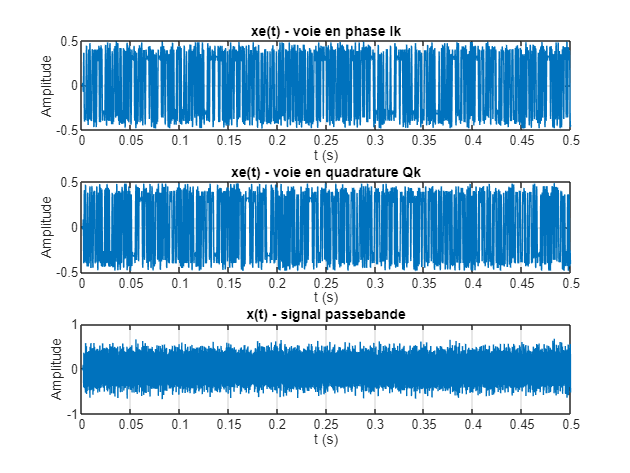


%% Plot signaux xe(t) et x(t)
figure;
subplot(3,1,1);
plot(t_test, real(xe_test));
title('xe(t) - voie en phase Ik'); xlabel('t (s)'); ylabel('Amplitude'); grid on;

subplot(3,1,2);
plot(t_test, imag(xe_test));
title('xe(t) - voie en quadrature Qk'); xlabel('t (s)'); ylabel('Amplitude'); grid on;

subplot(3,1,3);
plot(t_test, x_test);
title('x(t) - signal passebande'); xlabel('t (s)'); ylabel('Amplitude'); grid on;

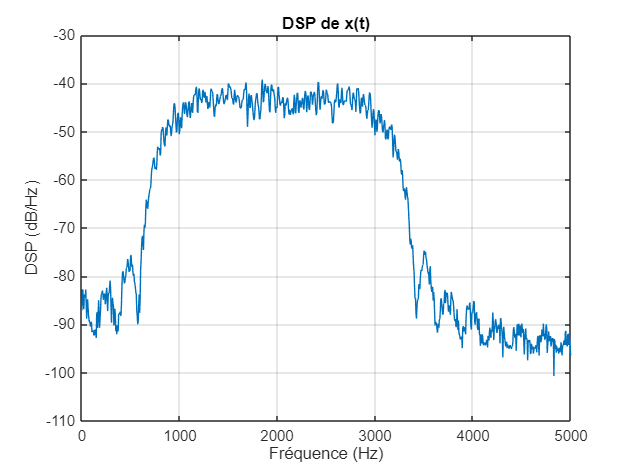


%% DSP de x(t)
figure;
[pxx, f] = pwelch(x_test, [], [], [], Fs);
plot(f, 10*log10(pxx));
title('DSP de x(t)'); xlabel('Fréquence (Hz)'); ylabel('DSP (dB/Hz)'); grid on;

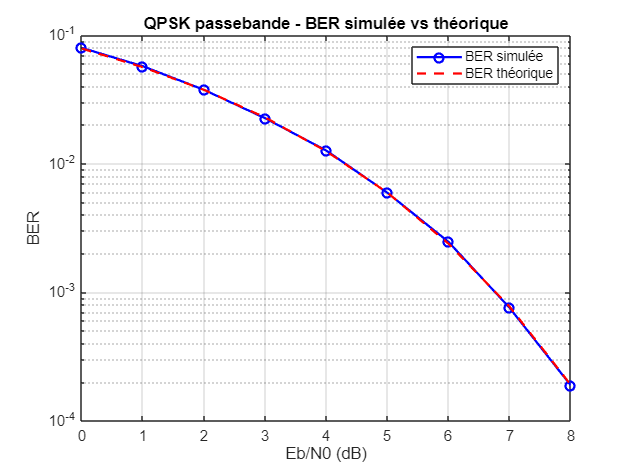


%% Tracé BER
figure;
semilogy(tab_EbN0_dB, BER_simu, 'bo-', 'LineWidth', 1.5, 'MarkerSize', 6); hold on;
semilogy(tab_EbN0_dB, BER_theo, 'r--', 'LineWidth', 1.5);
legend('BER simulée', 'BER théorique');
xlabel('Eb/N0 (dB)'); ylabel('BER');
title('QPSK passebande - BER simulée vs théorique');
grid on;